syms s t
f = sin(t)

$$f = \sin\left(t\right)$$

laplace(f, t, s)

$$ans = \frac{1}{s^{2}+1}$$

laplace(cos(t))

$$ans = \frac{s}{s^{2}+1}$$

laplace(exp(2*t))

$$ans = \frac{1}{s-2}$$

laplace(sin(3*t)*cos(2*t))

$$ans = \frac{1}{2\,\left(s^{2}+1\right)}+\frac{5}{2\,\left(s^{2}+25\right)}$$

laplace(sin(t)/t)

$$ans = \mathrm{atan}\left(\frac{1}{s}\right)$$

laplace((t^2)*sin(t))

$$ans = \frac{8\,s^{2}}{{\left(s^{2}+1\right)}^{3}}-\frac{2}{{\left(s^{2}+1\right)}^{2}}$$

For piecewise functions


$$f\left(t\right)\left\lbrace \begin{array}{cc}
t^2  & 0\le t<\pi \;\\
t & t\ge \pi 
\end{array}\right.$$


syms s t
f = t^2*(heaviside(t-0)-heaviside(t-pi))+t*heaviside(t-pi)

$$f = t^{2}\,\left(\mathrm{heaviside}\left(t\right)-\mathrm{heaviside}\left(t-\pi \right)\right)+t\,\mathrm{heaviside}\left(t-\pi \right)$$

simplify(laplace(f))

$$ans = \frac{{\mathrm{e}}^{-\pi \,s}\,\left(s+2\,{\mathrm{e}}^{\pi \,s}-2\,\pi \,s+\pi \,s^{2}-s^{2}\,\pi^{2}-2\right)}{s^{3}}$$


$$f\left(t\right)\left\lbrace \begin{array}{cc}
\mathrm{cos}\left(t\right) & 0\le t<\pi \;\\
\mathrm{sin}\left(t\right) & t\ge \pi 
\end{array}\right.$$


f = cos(t)*(heaviside(t)-heaviside(t-pi))+sin(t)*heaviside(t-pi)

$$f = \sin\left(t\right)\,\mathrm{heaviside}\left(t-\pi \right)+\cos\left(t\right)\,\left(\mathrm{heaviside}\left(t\right)-\mathrm{heaviside}\left(t-\pi \right)\right)$$

syms satyajit
laplace(f, t, satyajit)

$$ans = \frac{\mathrm{satyajit}+\mathrm{satyajit}\,{\mathrm{e}}^{\pi \,\mathrm{satyajit}}}{{\mathrm{e}}^{\pi \,\mathrm{satyajit}}+{\mathrm{satyajit}}^{2}\,{\mathrm{e}}^{\pi \,\mathrm{satyajit}}}-\frac{{\mathrm{e}}^{-\pi \,\mathrm{satyajit}}}{{\mathrm{satyajit}}^{2}+1}$$


$$f\left(t\right)=\left\lbrace \begin{array}{cc}
1 & 0<t<1\\
t & 1\le t<2
\end{array}\right.$$


f = 1*(heaviside(t-0)-heaviside(t-1)+...
    t*heaviside(t-1)-heaviside(t-2))+...
    t^2*(heaviside(t-2))

$$f = \mathrm{heaviside}\left(t\right)-\mathrm{heaviside}\left(t-2\right)-\mathrm{heaviside}\left(t-1\right)+t\,\mathrm{heaviside}\left(t-1\right)+t^{2}\,\mathrm{heaviside}\left(t-2\right)$$

laplace(f)

$$ans = \frac{3\,{\mathrm{e}}^{-2\,s}}{s}+\frac{{\mathrm{e}}^{-s}}{s^{2}}+\frac{4\,{\mathrm{e}}^{-2\,s}}{s^{2}}+\frac{2\,{\mathrm{e}}^{-2\,s}}{s^{3}}+\frac{1}{s}$$


$$f\left(t\right)=\left\lbrace \begin{array}{cc}
\mathrm{cos}\left(t\right) & 0<t<\pi \\
1 & \pi \le t<2\pi \;\\
\mathrm{sin}\left(t\right) & t\ge 2\pi \;
\end{array}\right.$$


f = cos(t)*(heaviside(t-0)-heaviside(t-pi))+...
    1*(heaviside(t-pi)-heaviside(t-2*pi))+...
    sin(t)*(heaviside(t-2*pi))

$$f = \mathrm{heaviside}\left(t-\pi \right)-\mathrm{heaviside}\left(t-2\,\pi \right)+\sin\left(t\right)\,\mathrm{heaviside}\left(t-2\,\pi \right)+\cos\left(t\right)\,\left(\mathrm{heaviside}\left(t\right)-\mathrm{heaviside}\left(t-\pi \right)\right)$$

laplace(f)

$$ans = \frac{{\mathrm{e}}^{-2\,\pi \,s}}{s^{2}+1}+\frac{s+s\,{\mathrm{e}}^{\pi \,s}}{{\mathrm{e}}^{\pi \,s}+s^{2}\,{\mathrm{e}}^{\pi \,s}}+\frac{{\mathrm{e}}^{-\pi \,s}}{s}-\frac{{\mathrm{e}}^{-2\,\pi \,s}}{s}$$

syms w t


$$f\left(t\right)=\left\lbrace \begin{array}{cc}
1 & -1\le t<1\\
0 & \mathrm{otherwise}
\end{array}\right.$$


f = 1*(heaviside(t+1)-heaviside(t-1))

$$f = \mathrm{heaviside}\left(t+1\right)-\mathrm{heaviside}\left(t-1\right)$$

FS = fourier(f, t, w)

$$FS = -\frac{-\sin\left(w\right)+\cos\left(w\right)\,\mathrm{i}}{w}+\frac{\sin\left(w\right)+\cos\left(w\right)\,\mathrm{i}}{w}$$

FS = simplify(FS)

$$FS = \frac{2\,\sin\left(w\right)}{w}$$

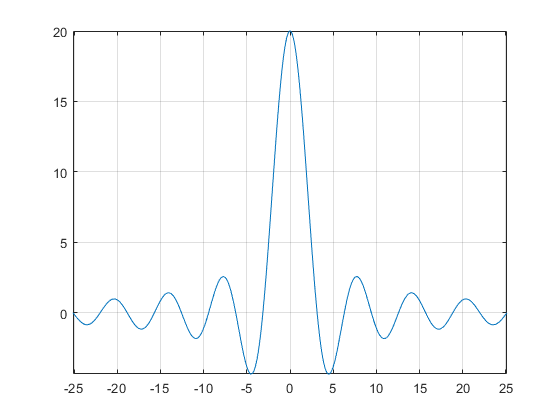

fplot(10*FS, [-8*pi 8*pi])
grid on


$$f\left(t\right)=\left\lbrace \begin{array}{cc}
1+t & -1\le t<0\\
1-t & 0\le t<1\\
0 & \mathrm{otherwise}
\end{array}\right.$$


f = (1+t)*(heaviside(t+1)-heaviside(t-0))+(1-t)*(heaviside(t-0)-heaviside(t-1))

$$f = \left(t-1\right)\,\left(\mathrm{heaviside}\left(t-1\right)-\mathrm{heaviside}\left(t\right)\right)+\left(t+1\right)\,\left(\mathrm{heaviside}\left(t+1\right)-\mathrm{heaviside}\left(t\right)\right)$$

fourier(f)

$$ans = \begin{array}{l} \frac{2}{w^{2}}+\frac{\sin\left(w\right)+\cos\left(w\right)\,\mathrm{i}}{w}+{\mathrm{e}}^{-w\,\mathrm{i}}\,\sigma_{2}-{\mathrm{e}}^{w\,\mathrm{i}}\,\sigma_{2}+{\mathrm{e}}^{w\,\mathrm{i}}\,\sigma_{1}\,\mathrm{i}-\frac{-\sin\left(w\right)+\cos\left(w\right)\,\mathrm{i}}{w}+{\mathrm{e}}^{-w\,\mathrm{i}}\,\sigma_{1}\,\mathrm{i}-2\,\pi \,\delta^{\prime }(w)\,\mathrm{i}\\ \mathrm{where}\\ \sigma_{1}=\pi \,\delta^{\prime }(w)+\frac{\mathrm{i}}{w^{2}}\\ \sigma_{2}=\pi \,\delta (w)-\frac{\mathrm{i}}{w} \end{array}$$


$$f\left(t\right)=\left\lbrace \begin{array}{cc}
1-|t| & |t|\le 1\\
0 & \mathrm{otherwise}
\end{array}\right.$$


f = (1-abs(t))*(heaviside(t+1)-heaviside(t-1))

$$f = \left(\left|t\right|-1\right)\,\left(\mathrm{heaviside}\left(t-1\right)-\mathrm{heaviside}\left(t+1\right)\right)$$

FS = fourier(f)

$$FS = \frac{2}{w^{2}}+\frac{{\mathrm{e}}^{w\,\mathrm{i}}\,\mathrm{i}}{w}-\frac{{\mathrm{e}}^{-w\,\mathrm{i}}}{w^{2}}-\frac{{\mathrm{e}}^{w\,\mathrm{i}}}{w^{2}}+\frac{\sin\left(w\right)+\cos\left(w\right)\,\mathrm{i}}{w}-\frac{-\sin\left(w\right)+\cos\left(w\right)\,\mathrm{i}}{w}-\frac{{\mathrm{e}}^{-w\,\mathrm{i}}\,\mathrm{i}}{w}$$

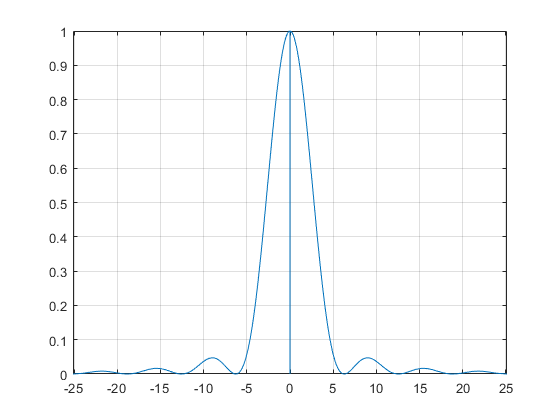

fplot(real(FS), [-8*pi 8*pi])
grid on;


$$f\left(t\right)=\left\lbrace \begin{array}{cc}
{\mathrm{te}}^t  & 0<t<\infty \\
0 & \mathrm{otherwise}
\end{array}\right.$$


f = t*exp(t)*(heaviside(t-0)-heaviside(t-(1/0)))

$$f = t\,{\mathrm{e}}^{t}\,\mathrm{heaviside}\left(t\right)$$

FS = fourier(f)

$$FS = \frac{1}{{\left(-1+w\,\mathrm{i}\right)}^{2}}+\mathrm{fourier}\left(t\,{\mathrm{e}}^{t},t,w\right)$$

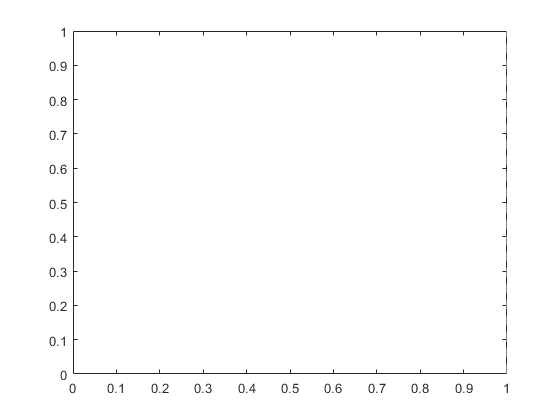

fplot(real(FS))

f = exp(1/t)/t*(heaviside(t-0)-heaviside(t-(1/0)))

$$f = \frac{{\mathrm{e}}^{1/t}\,\mathrm{heaviside}\left(t\right)}{t}$$

FS = fourier(f)

$$FS = \mathrm{fourier}\left(\frac{{\mathrm{e}}^{1/t}\,\mathrm{heaviside}\left(t\right)}{t},t,w\right)$$

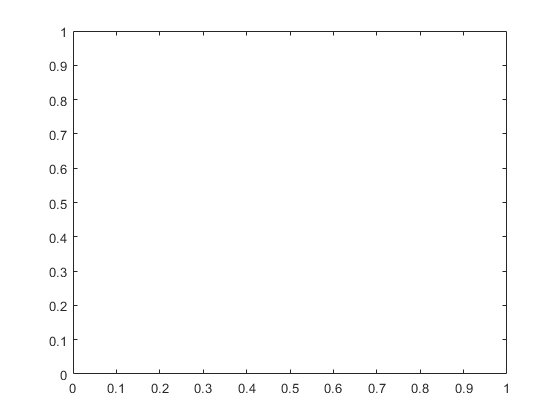

fplot(FS�)